# Proving Claims

## Left & Right for a fixed starting point & Number of steps to death for different initial positions

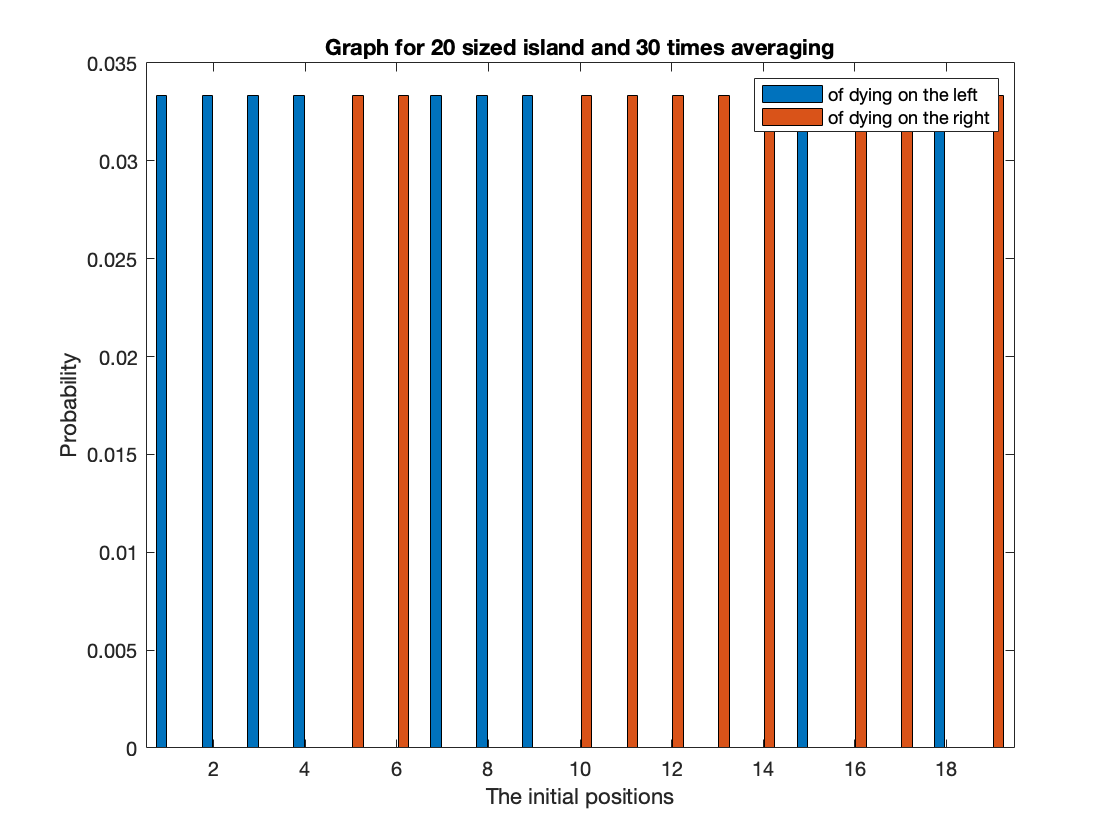

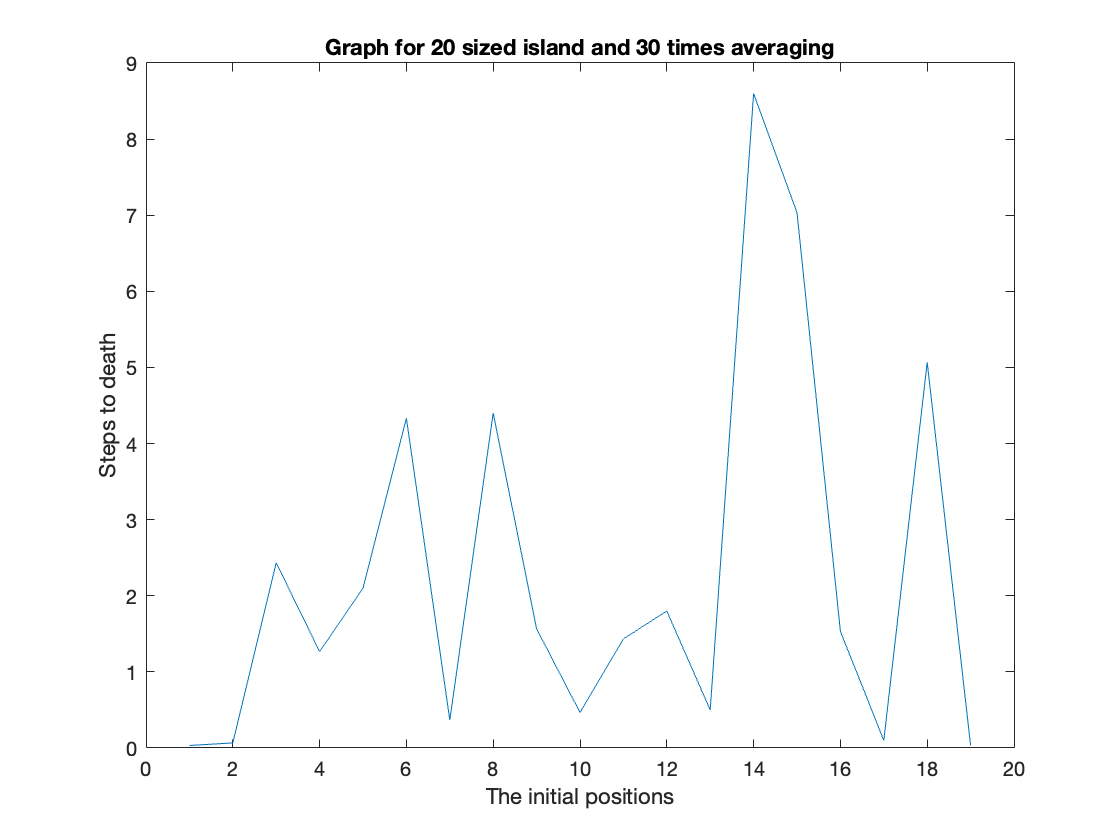

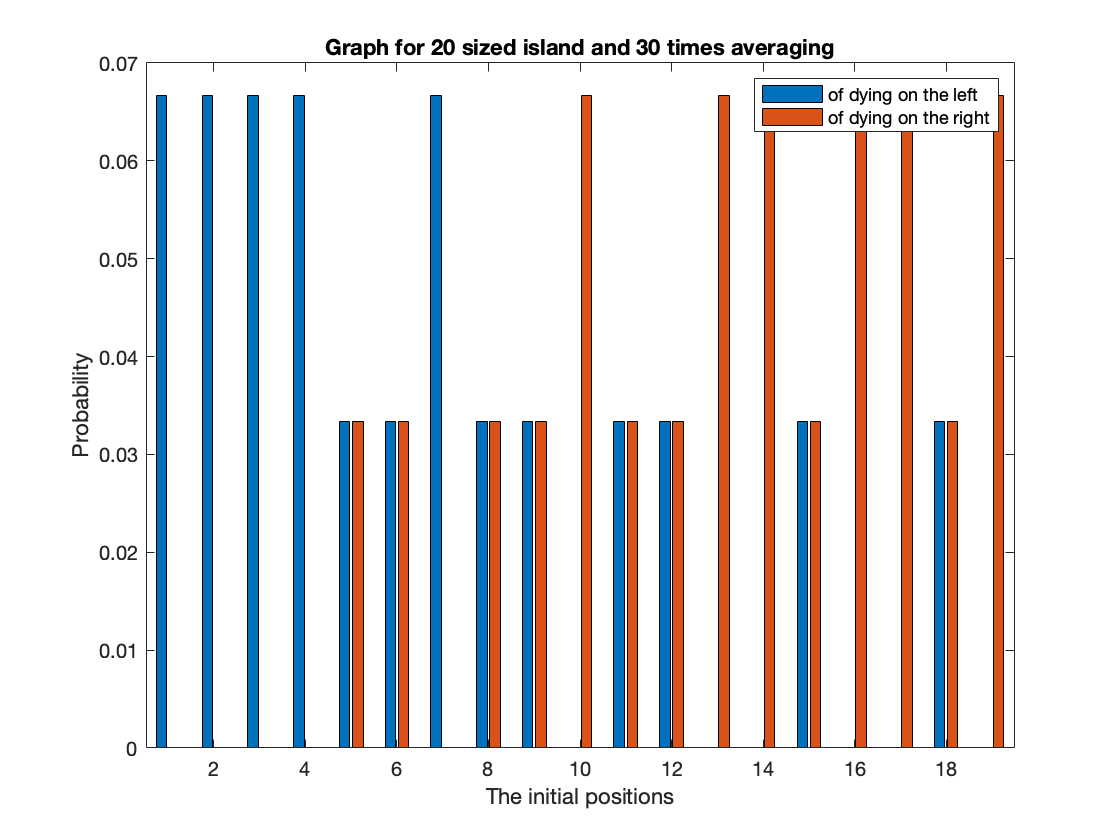

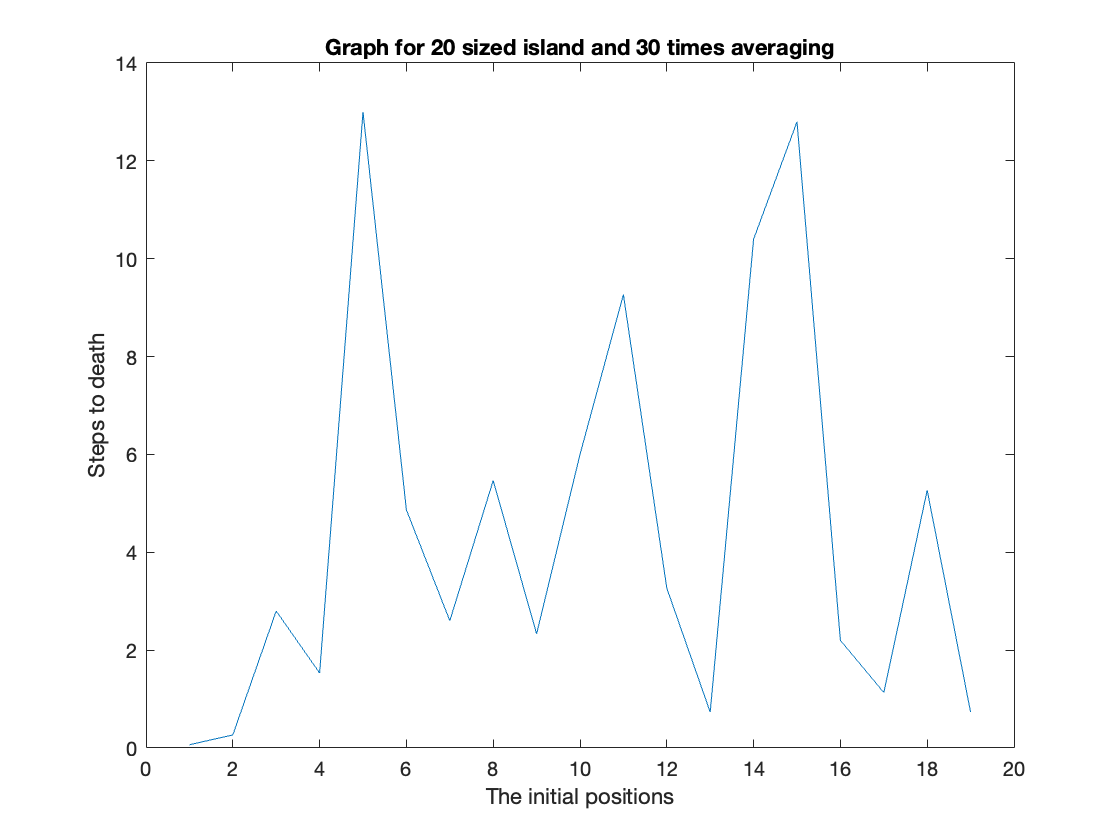

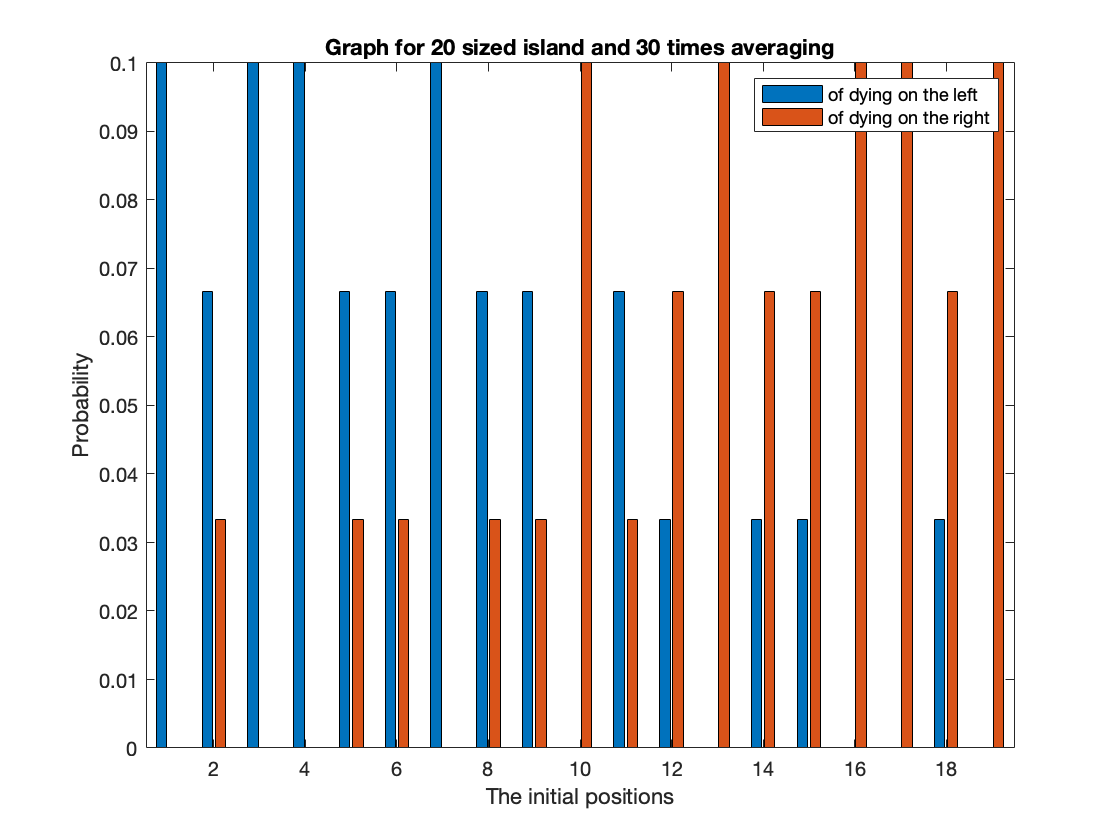

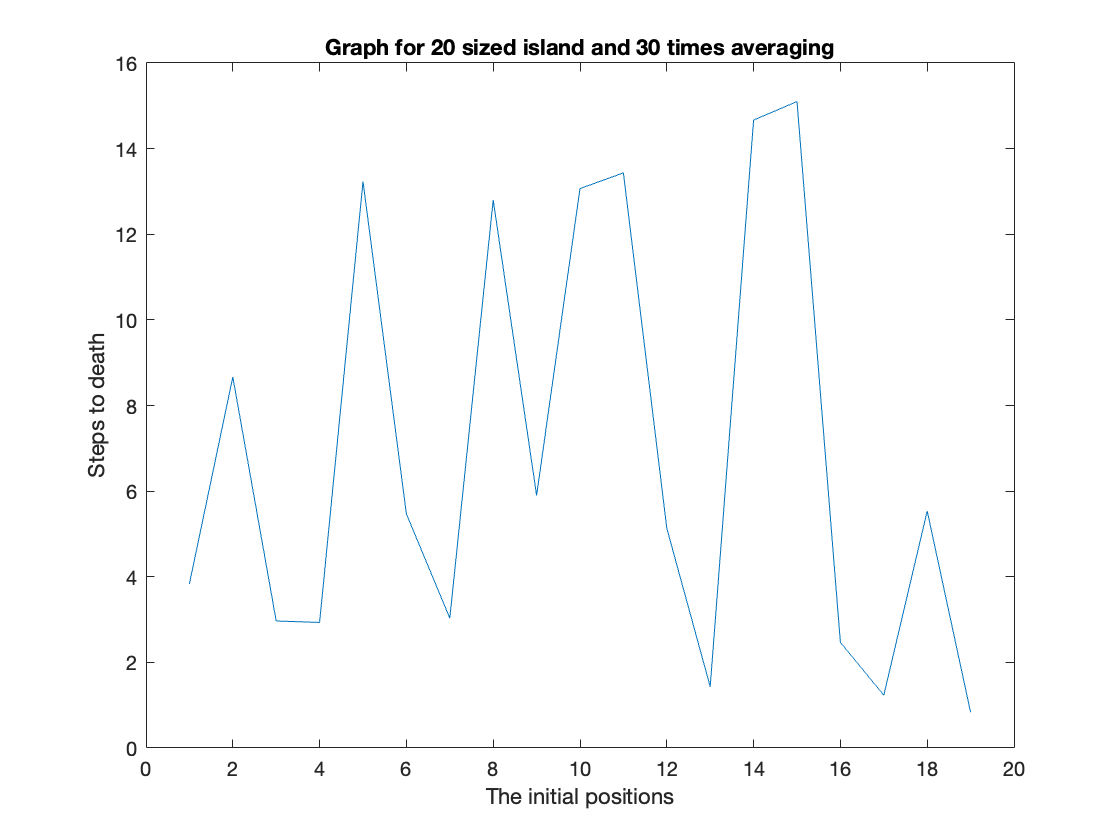

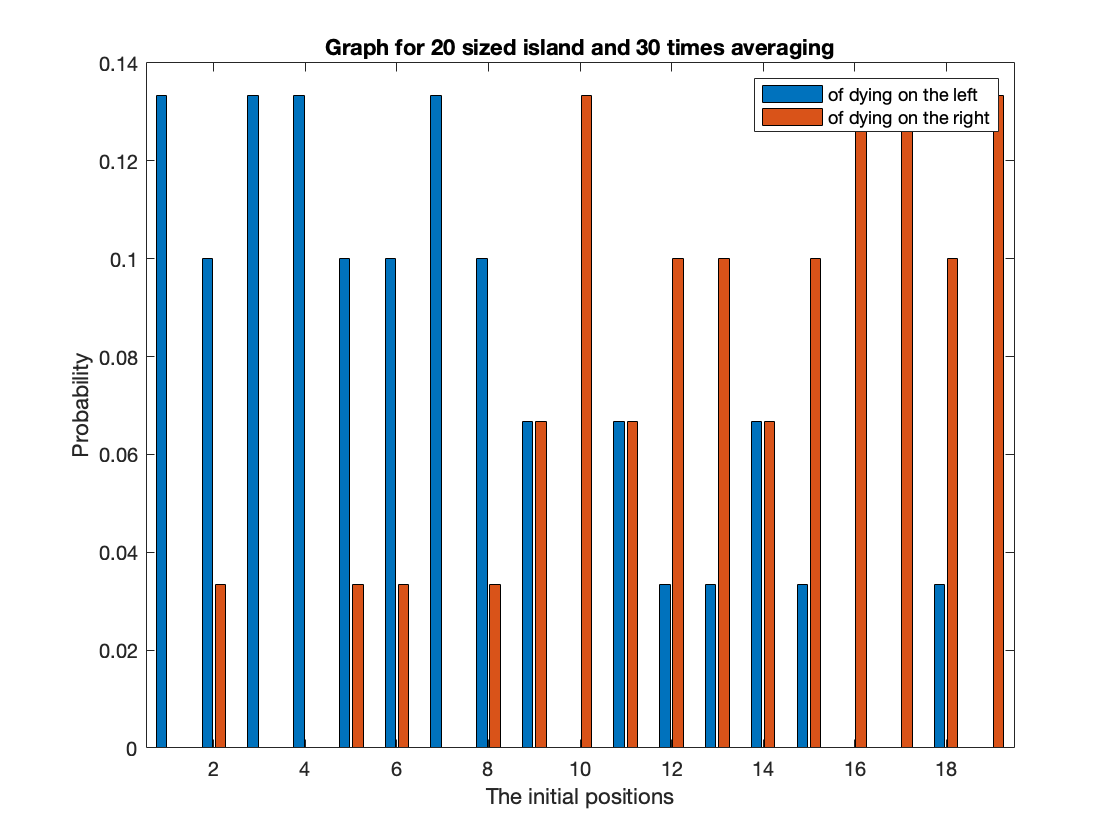

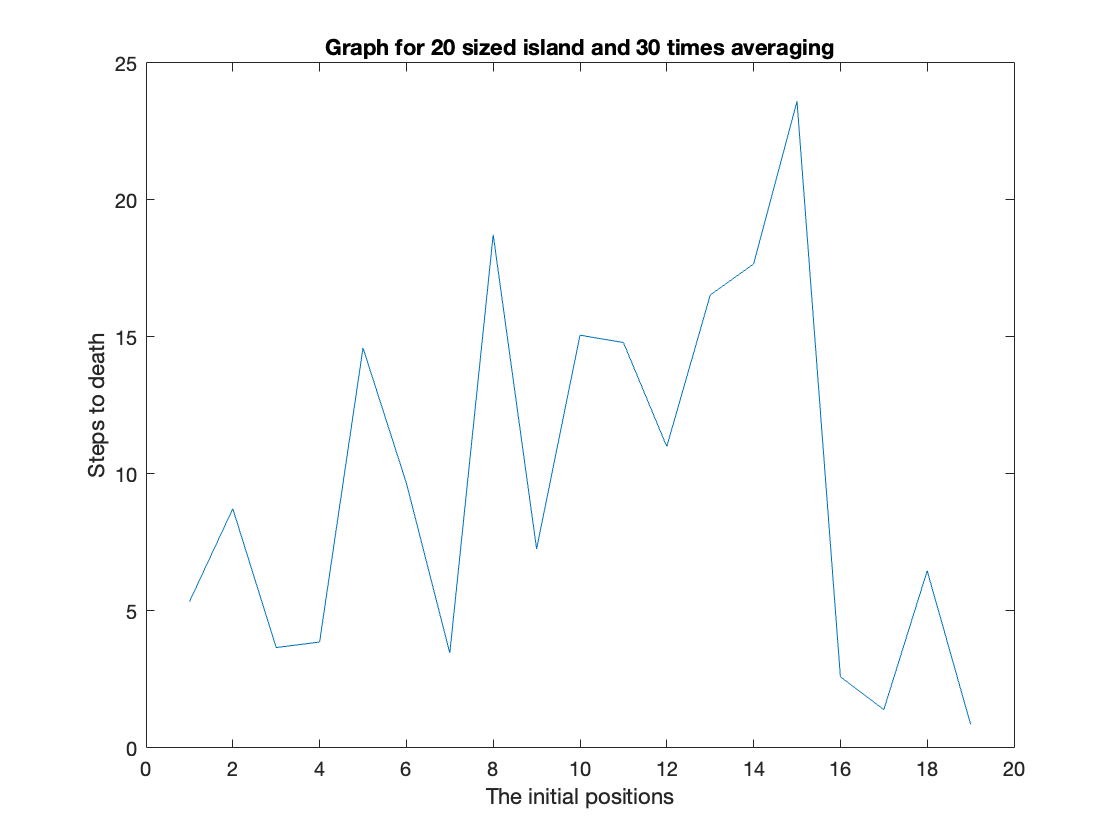

clc
clear
close all

average_scope = 30;

n_f = 20;

left_lst(1, n_f - 1) = 0;
right_lst(1, n_f - 1) = 0;


average_iterator = 1;

while average_iterator < average_scope
    % This runs for averaging

    left_count = 0;
    right_count = 0;

    position_iterator = 1;

    while position_iterator < n_f
        % This runs for the positions from 1 to (n_f - 1)
            
        [~, direction_death] = squeaky(n_f, position_iterator);
        
        if direction_death == -1
            left_lst(position_iterator) = left_lst(position_iterator) + 1;
    
        elseif direction_death == 1
            right_lst(position_iterator) = right_lst(position_iterator) + 1;
        end
            
        position_iterator = position_iterator + 1;
            
    end
    
    plot((1:n_f - 1), left_lst / average_scope, (1:n_f - 1), right_lst / average_scope)

    M(position_iterator) = getframe();

    average_iterator = average_iterator + 1;
end


title(sprintf("Graph for %d sized island and %d times averaging", n_f, average_scope))
xlabel("The initial positions")
ylabel("Probability")
legend("of dying on the left", "of dying on the right")
